# Homework 2

## Problem 1 (1)

clear; clc;

syms x

f(x) = sqrt(x) - cos(x);

a_1 = 0;
b_1 = 1;
p_1 = (a_1 + b_1)/2

p_1 = 0.5000


vpa(f(a_1), 4)

$$ans = -1.0$$

vpa(f(b_1), 4)

$$ans = 0.4597$$

vpa(f(p_1), 4)

$$ans = -0.1705$$


a_2 = p_1;
b_2 = b_1;
p_2 = (a_2 + b_2)/2

p_2 = 0.7500


vpa(f(a_2), 4)

$$ans = -0.1705$$

vpa(f(b_2), 4)

$$ans = 0.4597$$

vpa(f(p_2), 4)

$$ans = 0.1343$$


a_3 = a_2;
b_3 = p_2;
p_3 = (a_3 + b_3)/2

p_3 = 0.6250

## Problem 2 (14)

clear; clc;

syms n x

TOL = 10^-4

TOL = 1.0000e-04


f(x) = x^2 - 3;

n = log2(1/TOL)

n = 13.2877


bisectionMethod(f, 1, 2, TOL)

n              a              b              p              f(p)           
1              1              2              1.5            -0.75          
2              1.5            2              1.75           0.0625         
3              1.5            1.75           1.625          -0.35938       
4              1.625          1.75           1.6875         -0.15234       
5              1.6875         1.75           1.7188         -0.045898      
6              1.7188         1.75           1.7344         0.0080566      
7              1.7188         1.7344         1.7266         -0.018982      
8              1.7266         1.7344         1.7305         -0.0054779     
9              1.7305         1.7344         1.7324         0.0012856      
10             1.7305         1.7324         1.7314         -0.0020971     
11             1.7314         1.7324         1.7319         -0.00040603    
12             1.7319         1.7324         1.7322         0.0004397      
13          

ans = 1.7321

## Problem 3 (10)

clear; clc;

syms x n

g(x) = 2^(-x)

$$g(x) = \frac{1}{2^{x}}$$

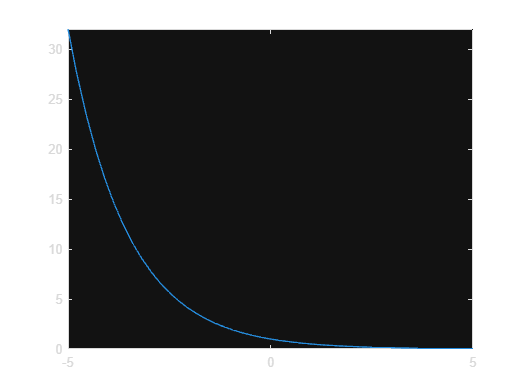

fplot(g)


vpa(g(1/3), 4)

$$ans = 0.7937$$

vpa(g(1), 4)

$$ans = 0.5$$


vpa(subs(diff(g, x), x, 1/3), 4)

$$ans(x) = -0.5502$$


n_sol = vpasolve(0.551^n*(2/3)==10^-4, n)

$$n\_sol = 14.772773267990065312154981867054$$


fixedPoint(g, 2/3, 10^-4);

n              p_n            |p_n-p_{n-1}|  
1              0.62996        0.036706       
2              0.64619        0.016234       
3              0.63896        0.0072304      
4              0.64217        0.0032103      
5              0.64075        0.0014274      
6              0.64138        0.00063427     
7              0.6411         0.00028192     
8              0.64122        0.00012529     
9              0.64117        5.5684e-05     


## Problem 4 (1)

clear; clc;

syms x

p_0 = 1;

f(x) = x^2 - 6

$$f(x) = x^{2}-6$$

f_prime(x) = diff(f, x)

$$f\_prime(x) = 2\,x$$


p_1 = p_0 - f(p_0)/f_prime(p_0)

$$p\_1 = \frac{7}{2}$$

p_2 = p_1 - f(p_1)/f_prime(p_1)

$$p\_2 = \frac{73}{28}$$

## Problem 5 (12a)

clear; clc;

syms x

f(x) = x^2 - 4*x + 4 - log(x)

$$f(x) = x^{2}-\log\left(x\right)-4\,x+4$$

g = @(x) x^2 - 4*x + 4 - log(x)

g = function_handle with value:
    @(x)x^2-4*x+4-log(x)



NewtonMethod(f, 1.5, 10^-7);

n              p_n            |p_n-p_{n-1}|  
1              1.406721       0.09327906     
2              1.41237        0.005649022    
3              1.412391       2.121447e-05   
4              1.412391       2.988791e-10   


secantMethod(g, 1, 2, 10^-7);

n              p_n            |p_n-p_{n-1}|  
2              1.590616       0.4093839      
3              1.284548       0.3060683      
4              1.427966       0.1434183      
5              1.413635       0.01433147     
6              1.412378       0.001256454    
7              1.412391       1.299672e-05   
8              1.412391       1.073098e-08   


NewtonMethod(f, 3, 10^-7);

n              p_n            |p_n-p_{n-1}|  
1              3.059167       0.05916737     
2              3.057106       0.002061319    
3              3.057104       2.504693e-06   
4              3.057104       3.698235e-12   


secantMethod(g, 2, 4, 10^-7);

n              p_n            |p_n-p_{n-1}|  
2              2.419219       1.580781       
3              2.75604        0.3368211      
4              3.317023       0.5609828      
5              3.009769       0.3072535      
6              3.050671       0.04090175     
7              3.057289       0.006618332    
8              3.057103       0.0001861977   
9              3.057104       7.059887e-07   
10             3.057104       7.719825e-11   


## Problem 6 (4b)

clear; clc;

syms x

coeffs = [1 -2 -12 16 -40];

f(x) = poly2sym(coeffs)

$$f(x) = x^{4}-2\,x^{3}-12\,x^{2}+16\,x-40$$

vpa(f(0.5835597))

$$ans = -35.031032165320712500205913895326$$

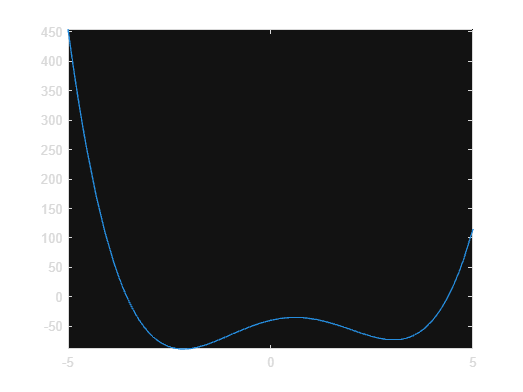


fplot(poly2sym(coeffs))


MuellerMethod(coeffs, 1, 2, 3, 10^-5);

n              p                   f(p)           
3              -0.7047 +0      i   -56.288        
4              0.65918 +3.214  i   209.54         
5              0.27268 +0.53586i   -32.695        
6              0.38851 +1.3029 i   -10.019        
7              0.542   +1.4709 i   -1.2194        
8              0.58457 +1.4936 i   -0.035052      
9              0.58356 +1.4942 i   5.8656e-05     
10             0.58356 +1.4942 i   -3.4301e-10    


MuellerMethod(coeffs, -1, -2, -3, 10^-5);

n              p                   f(p)           
3              -3.8366 +0      i   51.588         
4              -3.5245 +0      i   -3.5838        
5              -3.5478 +0      i   -0.058736      
6              -3.5482 +0      i   -4.3176e-05    
7              -3.5482 +0      i   4.1489e-11     


MuellerMethod(coeffs, 5, 6, 7, 10^-5);

n              p                   f(p)           
3              4.3964  -0.56232i   -22.392        
4              3.8375  -0.59332i   -70.125        
5              4.4484  -0.099854i   8.445          
6              4.3801  -0.0058419i   -0.13351       
7              4.3811  -6.0609e-05i   -0.0030177     
8              4.3811  -5.4476e-09i   4.1537e-08     
9              4.3811  -2.1934e-16i   -7.1054e-14    


## Problem 7 (6)

clear; clc;

n = 1/(5e-2)

n = 20